Problem 6.67 (a, b)

Use the MATLAB command **pzmap** to plot the poles and zeros of the following systems:

(a) $H(s) = \frac {s^3+1}{s^4+2s^2+1}$

(b) $A= \left[\matrix{ 1 & 2 \cr 1 &-6} \right]; b= \left[\matrix{ 1 & \cr 2} \right]; c = [\matrix{0 & 1}];D = [0]$

## Part A

clc
clear
num= [2 0 10];
den = [1 0 2 4];
z = roots(num);
disp('zeros:')

zeros:


disp(z)

     0.0000e+000 +  2.2361e+000i
     0.0000e+000 -  2.2361e+000i



r = roots(den);
disp('poles:')

poles:


disp(r)

   589.7545e-003 +  1.7445e+000i
   589.7545e-003 -  1.7445e+000i
    -1.1795e+000 +  0.0000e+000i



sys = tf(num,den)

sys =
 
   2 s^2 + 10
  -------------
  s^3 + 2 s + 4
 
Continuous-time transfer function.



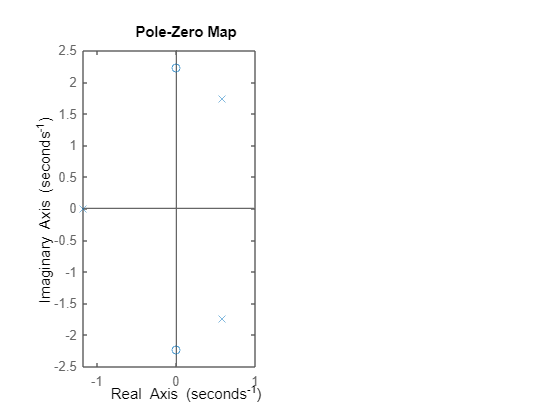

figure(1)
subplot(1, 2, 1);  
pzmap(sys)

## Part B

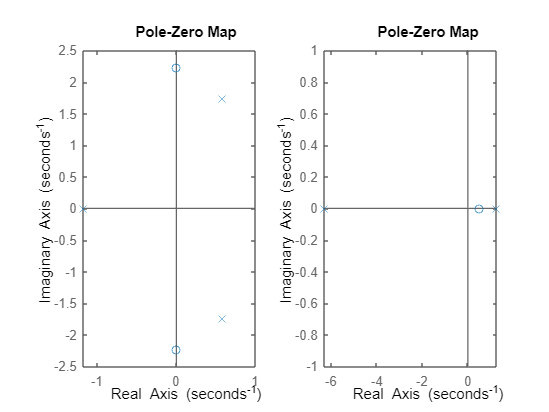

clc
clear
A = [1, 2; 1, -6];
b = [1; 2];
c = [0, 1];
D = 0; 
sys = ss(A,b,c,D);
figure(1)
subplot(1, 2, 2);  
pzmap(sys)